rootdir = '/Users/nbertelsen/projects/cmi_eeg_rs_H';
resultsdir = fullfile(rootdir, "results/reval/global");
plotdir = fullfile(rootdir, "plots/reval/global");
eeglabdir = '/Users/nbertelsen/Documents/MATLAB/eeglab_20201226'; 

## Initiate eeglab

cd(eeglabdir), eeglab('nogui'); cd(rootdir)

eeglab: options file is ~/eeg_options.m
EEGLAB: adding "Adjust" v1.1.1 (see >> help eegplugin_adjust)
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v1.04 (see >> help eegplugin_cleanline)
EEGLAB: adding "EEGBrowser" v? (see >> help eegplugin_EEGBrowser)
EEGLAB: adding "FASTER1.2.3b" v? (see >> help eegplugin_FASTER)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v? (see >> help eegplugin_iclabel)
EEGLAB: adding "IC_MARC-main" v? (see >> help eegplugin_icmarc)
EEGLAB: adding "MFFMatlabIO" v3.6 (see >> help eegplugin_mffmatlabio)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)
EEGLAB: adding "Viewprops" v1.5.4 (see >> help eegplugin_viewprops)
EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)
EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v? (see >> help eegplu

## Import data

fn_rseo = '13_pls_rsopen_ALL_BSRrev_LV1.csv';
fn_rsec = '13_pls_rsclosed_ALL_BSR_LV1.csv';

dt_rseo_original = readtable(fullfile(resultsdir, fn_rseo));
dt_rsec_original = readtable(fullfile(resultsdir, fn_rsec));

## Set parameters

electrodes = unique(dt_rseo_original.electrode);
n_channels = size(electrodes, 1);

## Load electrode structure for topoplotting and match electrode names

load(fullfile(rootdir, 'code', 'chanlocs_struct.mat'));
chanlocs_struct(93).labels = 'Cz'; % rename channel '129' in chainlock 'Cz' for congruence with our channel names
if sum(ismember({chanlocs_struct.labels}', electrodes)) == 93
electrodes = {chanlocs_struct.labels}';
else
    disp('Electrode name mismatch!')
    return
end

% unstack and reorder
dt_rseo = unstack(dt_rseo_original, "BSR", "block", "VariableNamingRule", "modify");
[~,loc_rseo] = ismember(electrodes, dt_rseo.electrode);
dt_rseo = dt_rseo(loc_rseo, :);

dt_rsec = unstack(dt_rsec_original, "BSR", "block", "VariableNamingRule", "modify");
[~,loc_rsec] = ismember(electrodes, dt_rsec.electrode);
dt_rsec = dt_rsec(loc_rsec, :);


## set plotting parameters

colors2use = {'#ffffd9', '#edf8b1', '#c7e9b4', '#7fcdbb', '#41b6c4', '#1d91c0', '#225ea8', '#253494', '#081d58'};
mycolormap = customcolormap( [0, .125, .25, .375, .5, .625, .75, .875, 1],...
    colors2use);

% set constants
t_sz = 26;
cb_range = [-10, 0, 10, 20, 30];
cb_lim = [-10, 30];
cb_title_sz = 26;
cb_tick_sz = 18;
cb_pos = [0.8491 0.2 .06 .6];
sbt_sz = 22;
t_sz = 26;


**RSOPEN - topoplots of d values**

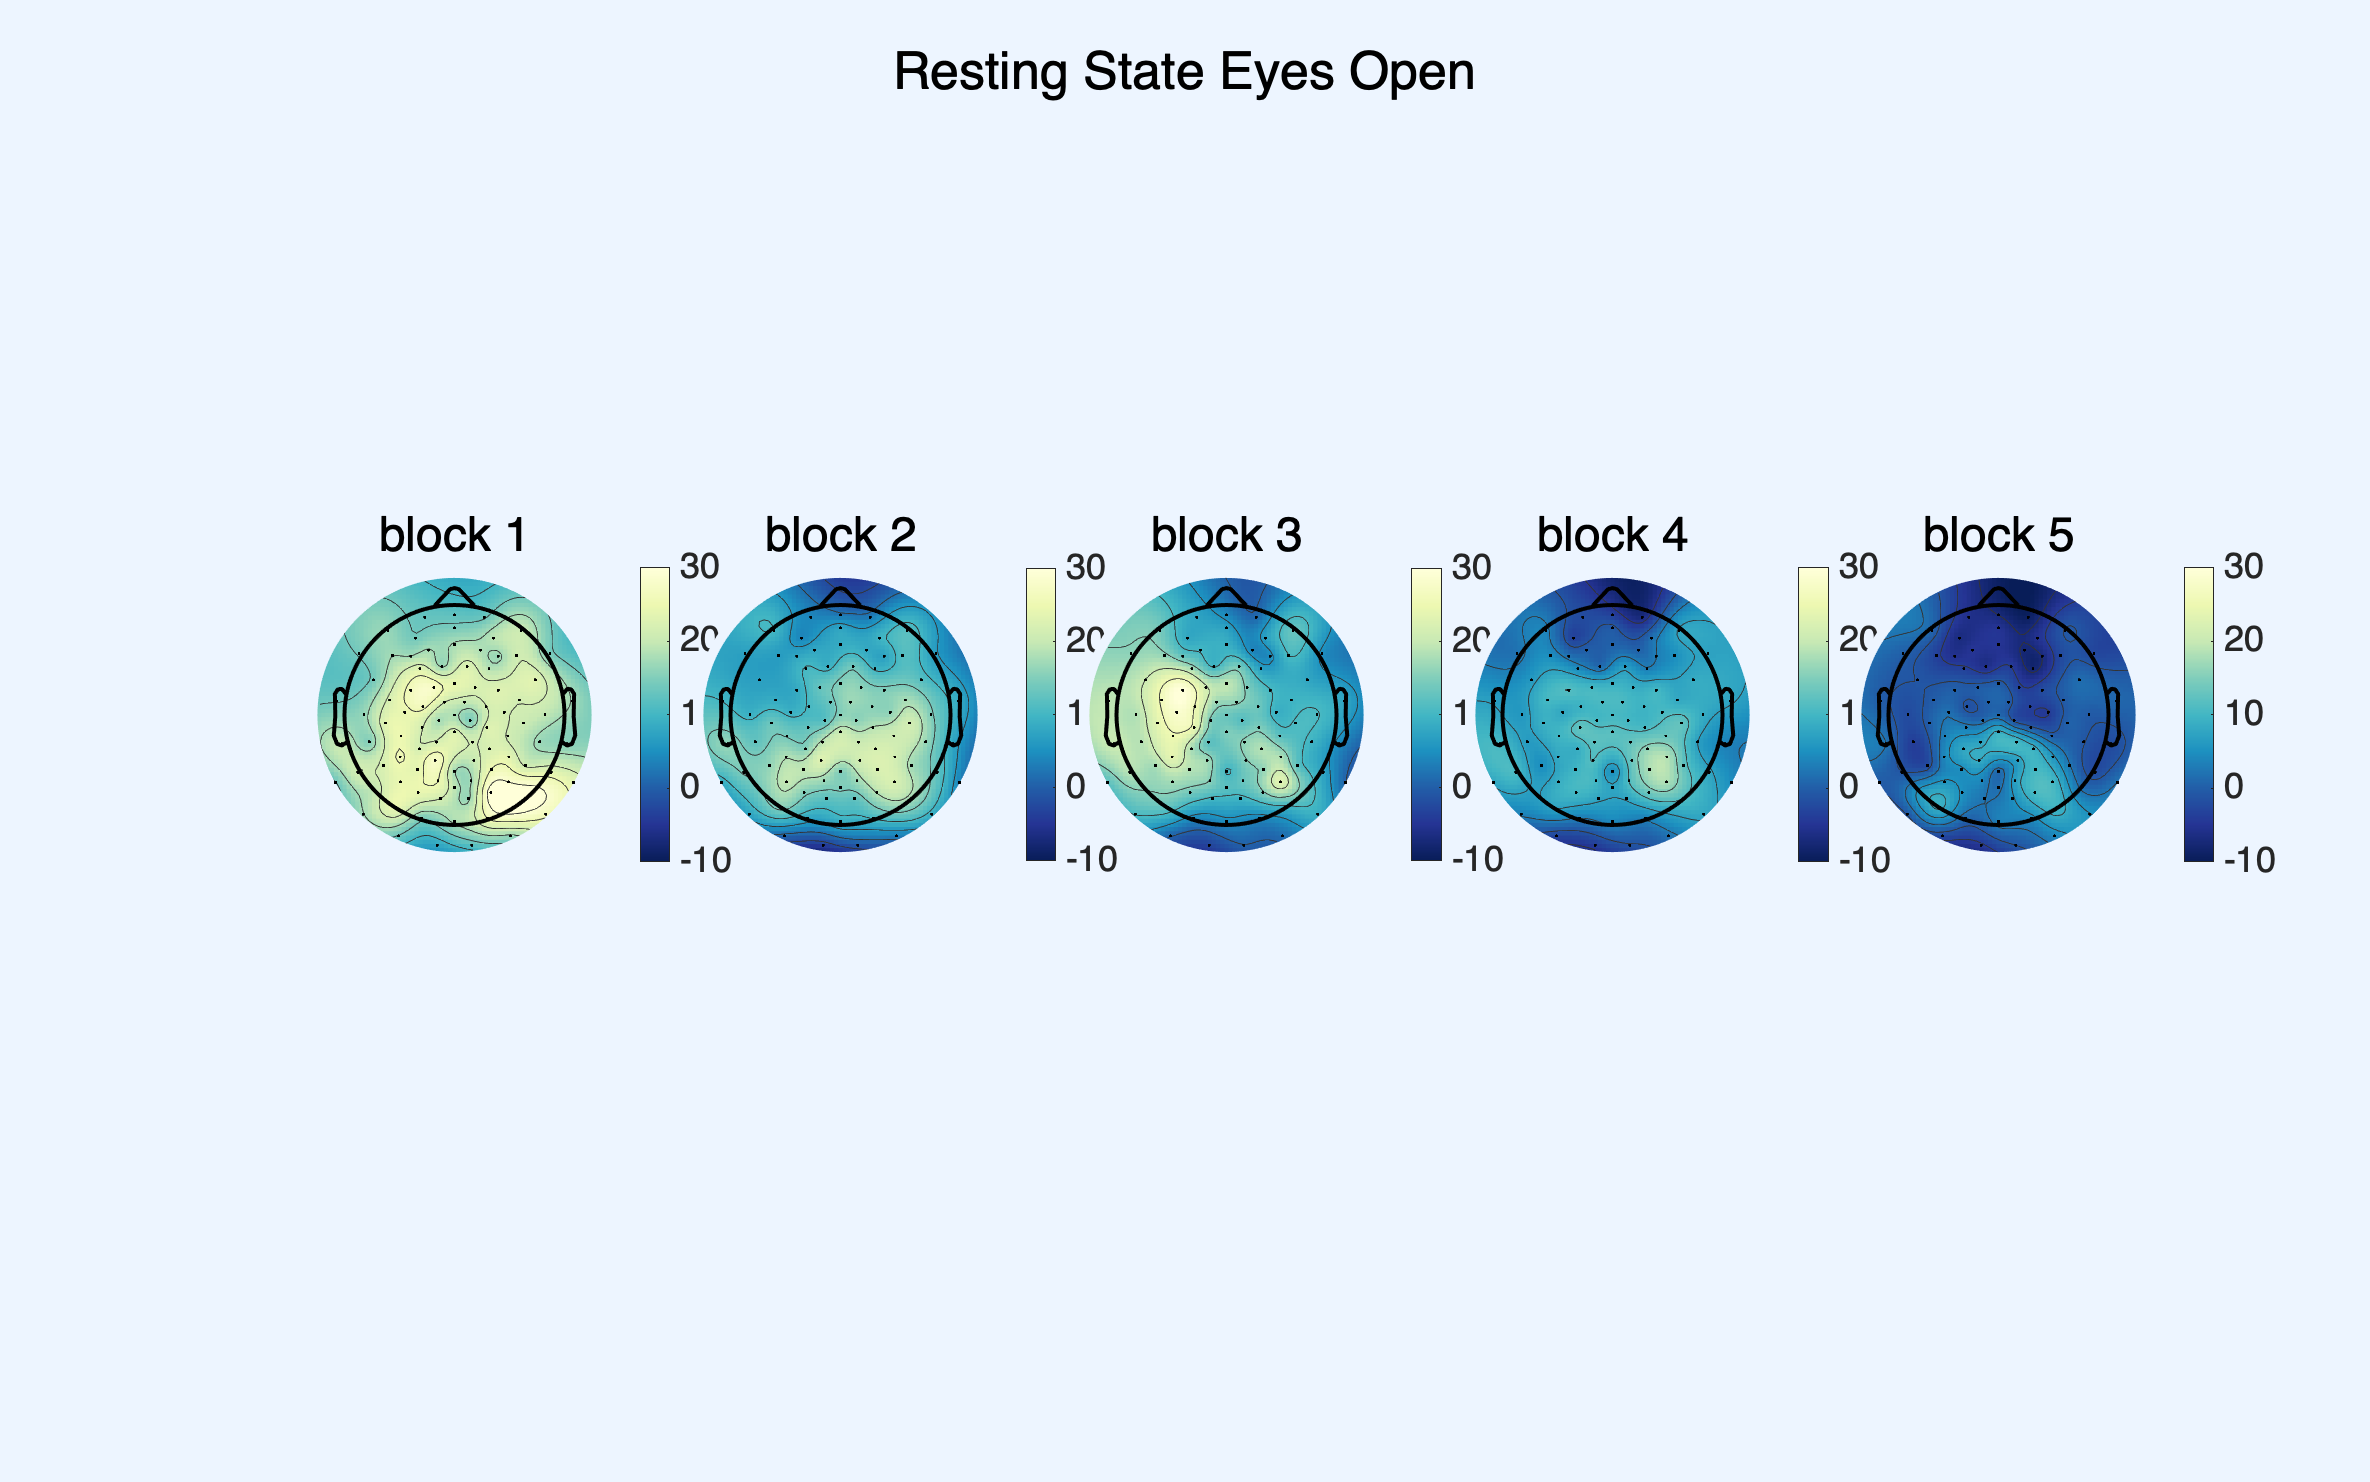

f1 = figure();

% block 1
subplot(1, 5, 1), topoplot(dt_rseo.block1, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %-8-32
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick', cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 1');

% block 2
subplot(1, 5, 2), topoplot(dt_rseo.block2, chanlocs_struct, ... 
    'electrodes', 'on', 'colormap', mycolormap); %-5-23
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1), s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 2');

% plot
subplot(1, 5, 3), topoplot(dt_rseo.block3, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %-4-31
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1), s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 3');

% plot
subplot(1, 5, 4), topoplot(dt_rseo.block4, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %-7-18
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'fontsize', sbt_sz);
subtitle('block 4');

% plot
subplot(1, 5, 5), topoplot(dt_rseo.block5, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %-10-11
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'fontsize', sbt_sz);
subtitle('block 5');

sgtitle('Resting State Eyes Open', 'Color', 'Black', 'FontSize', t_sz);
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f1, fullfile(plotdir, 'rsopen/topoplots', '17_adjH_topoplot_PLS_BSR.jpg'))

## heatmap

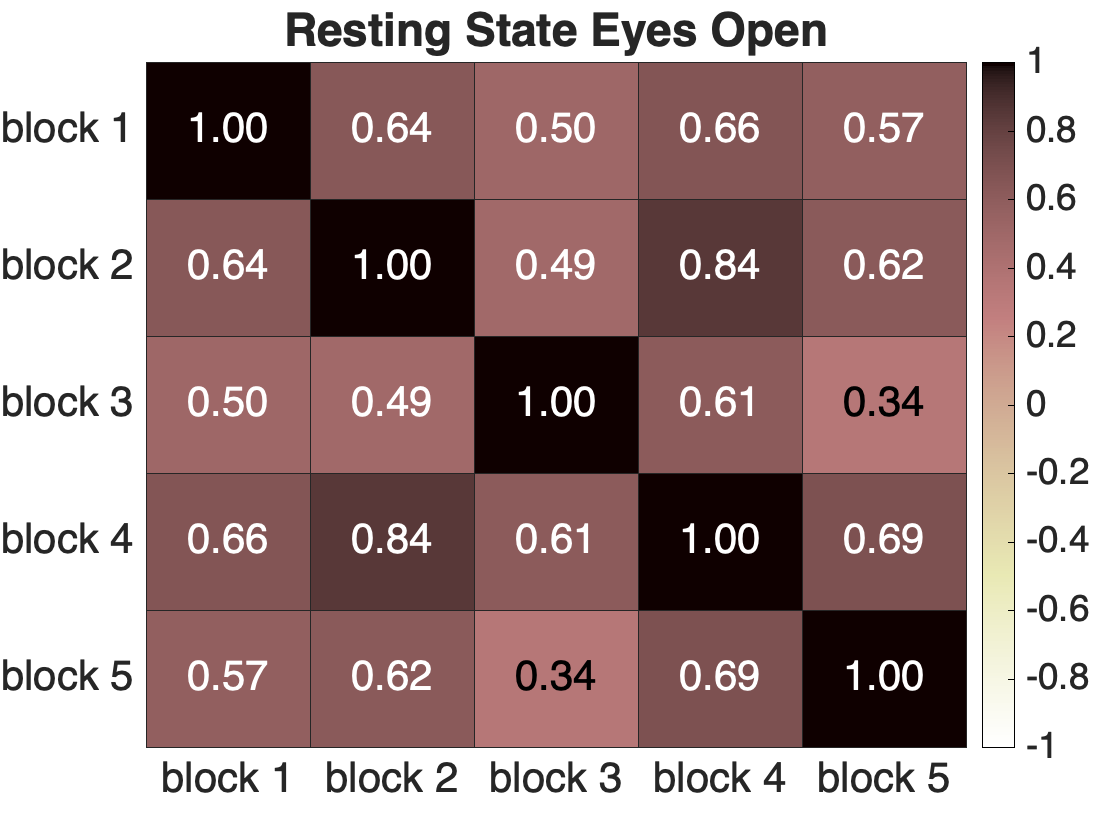

dt2use = table2array(dt_rseo(:, 2:end));
corr_mat = corr(dt2use);

f1b = figure();
xvalues = {'block 1','block 2','block 3','block 4','block 5'};
yvalues = {'block 1','block 2','block 3','block 4','block 5'};
h = heatmap(xvalues, yvalues, corr_mat); 
h.FontSize = 21;
colormap(flip(pink)); 
h.ColorLimits = [-1 1];
h.CellLabelFormat = '%.2f';

hCB=h.NodeChildren(2);
hCB.TickLabels = {-1, -.5, 0, .5, 1};

title('Resting State Eyes Open');
saveas(f1b, fullfile(plotdir, 'rsopen/pls', '17_adjH_corr_matrix_byblock_BSR.jpg'))

**RSCLOSED - topoplots of d values**

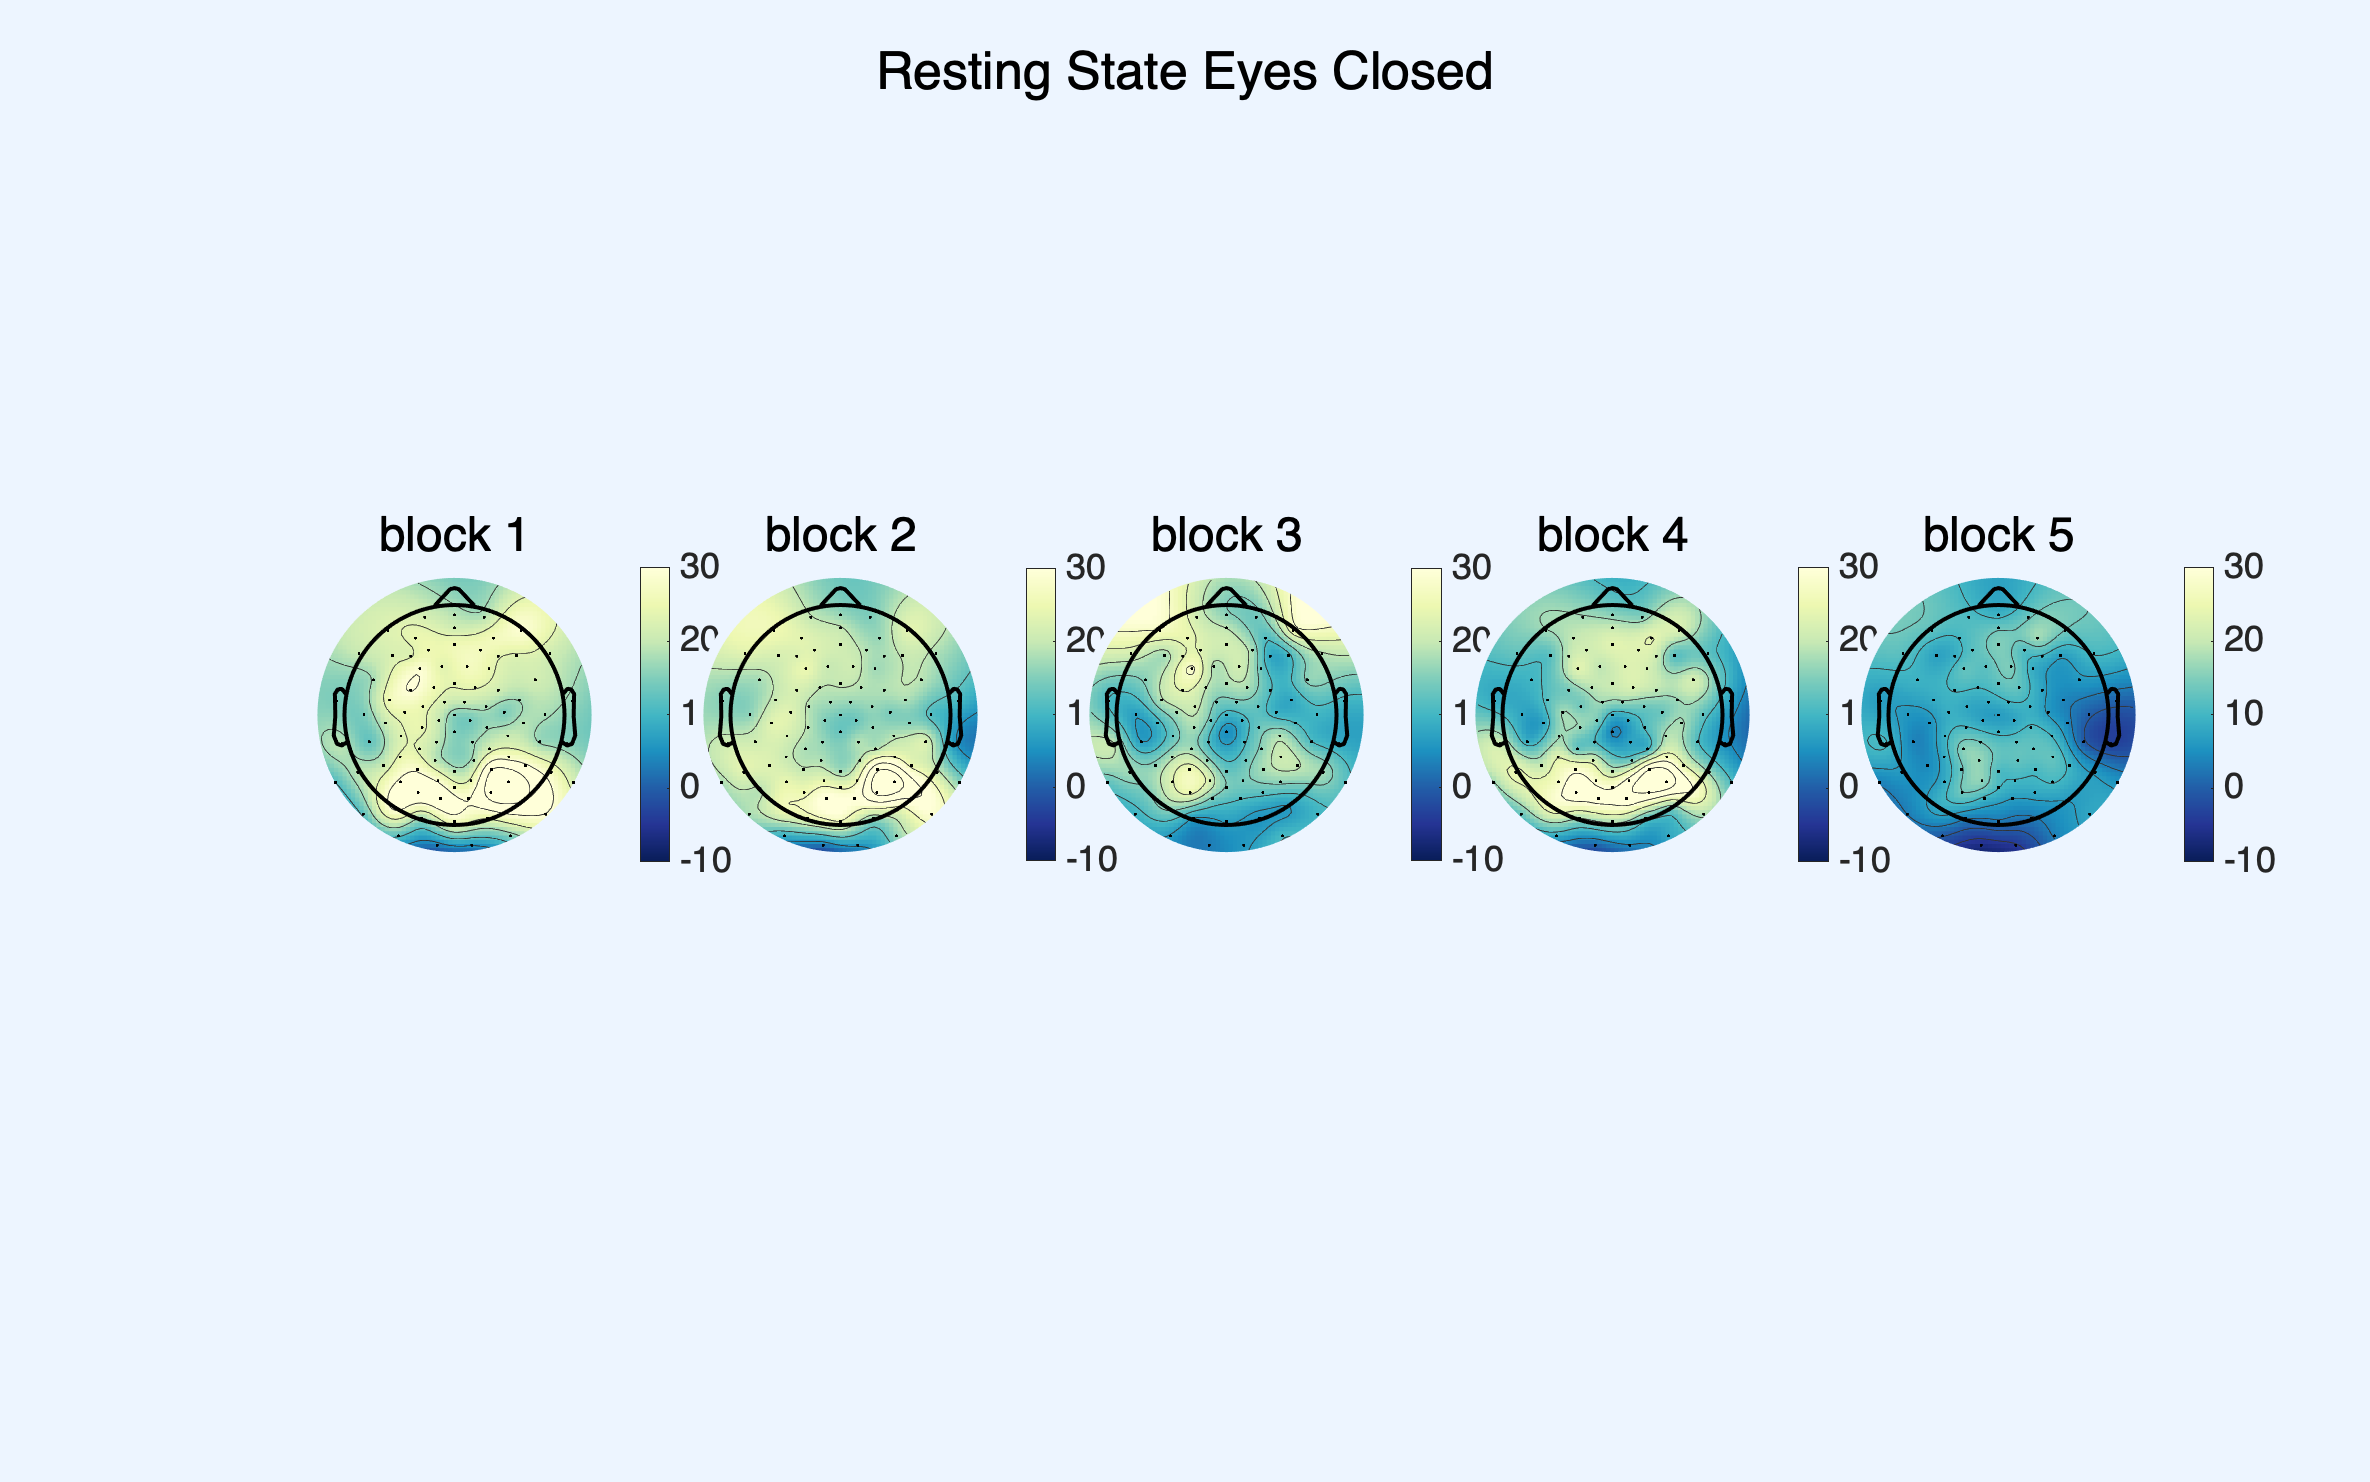

f2 = figure();

% block 1
subplot(1, 5, 1), topoplot(dt_rsec.block1, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %3-42
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick', cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 1');

% block 2
subplot(1, 5, 2), topoplot(dt_rsec.block2, chanlocs_struct, ... 
    'electrodes', 'on', 'colormap', mycolormap); %2-46
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 2');

% block 3
subplot(1, 5, 3), topoplot(dt_rsec.block3, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %3-29
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'FontSize', sbt_sz);
subtitle('block 3');

% block 4
subplot(1, 5, 4), topoplot(dt_rsec.block4, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %0-42
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'fontsize', sbt_sz);
subtitle('block 4');

% block 5
subplot(1, 5, 5), topoplot(dt_rsec.block5, chanlocs_struct, ...
    'electrodes', 'on', 'colormap', mycolormap); %-7-18
cb = colorbar; set(cb,'FontSize', cb_tick_sz); clim(cb_lim); set(cb,'YTick',cb_range); 
s = get(gca, 'Position'); set(gca, 'Position', [s(1) , s(2), s(3), s(4)], 'fontsize', sbt_sz);
subtitle('block 5');

sgtitle('Resting State Eyes Closed', 'Color', 'Black', 'FontSize', t_sz);
set(gcf, 'Position', get(0, 'Screensize'));
saveas(f2, fullfile(plotdir, 'rsclosed/topoplots', '17_adjH_topoplot_PLS_BSR.jpg'))

## heatmap

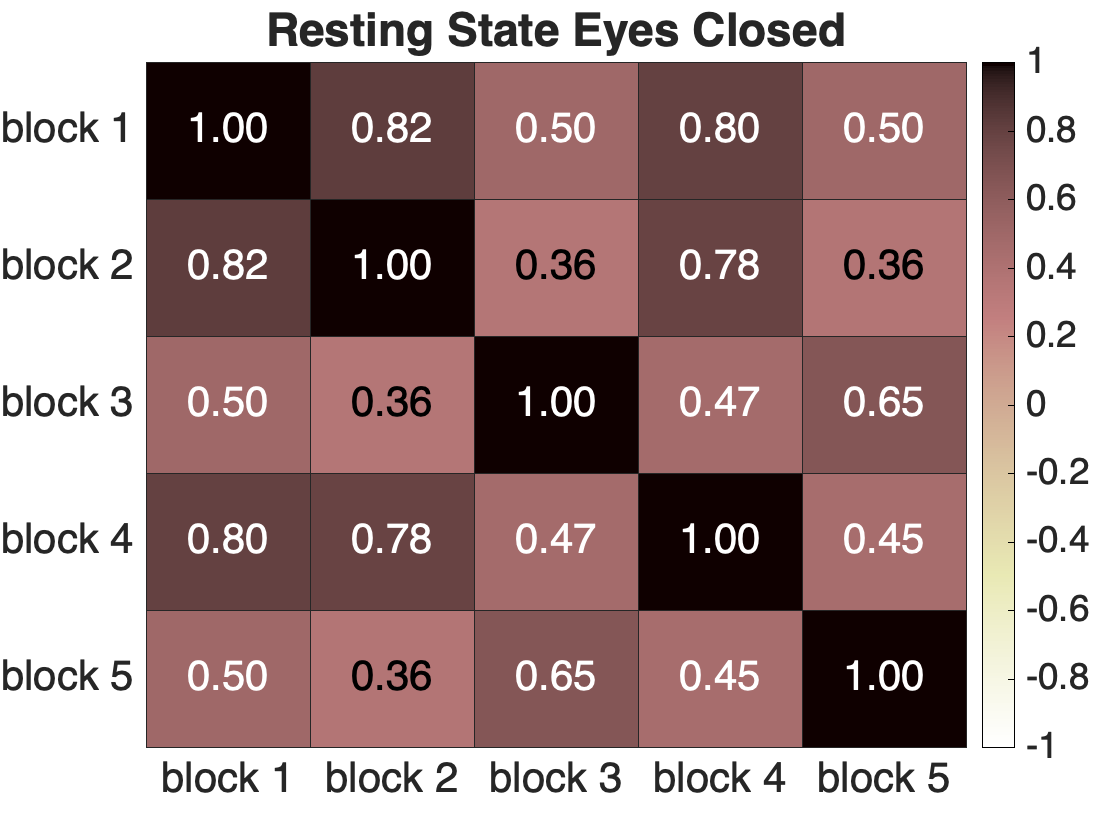

dt2use = table2array(dt_rsec(:, 2:end));
corr_mat = corr(dt2use);

f2b = figure();
xvalues = {'block 1','block 2','block 3','block 4','block 5'};
yvalues = {'block 1','block 2','block 3','block 4','block 5'};
h = heatmap(xvalues, yvalues, corr_mat); 
h.FontSize = 21;
colormap(flip(pink)); 
h.ColorLimits = [-1 1];
h.CellLabelFormat = '%.2f';

hCB=h.NodeChildren(2);
hCB.TickLabels = {-1, -.5, 0, .5, 1};

title('Resting State Eyes Closed');
saveas(f2b, fullfile(plotdir, 'rsclosed/pls', '17_adjH_corr_matrix_byblock_BSR.jpg'))